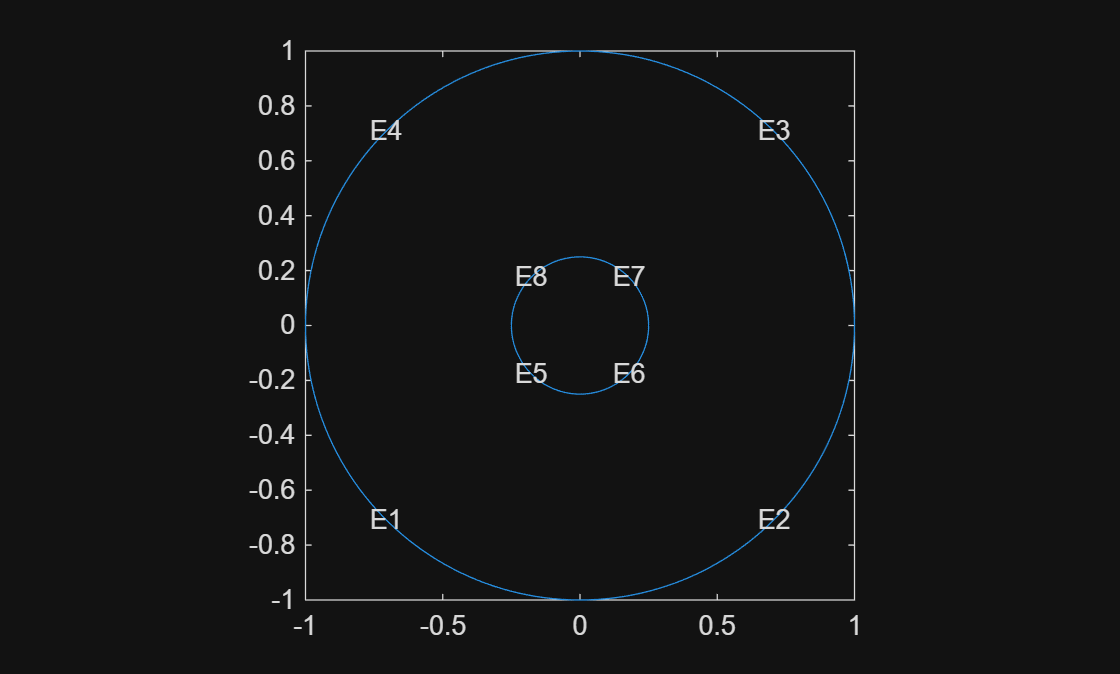

model = createpde;
R1 = [3,4,-2,2,2,-2,1,1,-1,-1]';
C2 = [1, 1, .2,0.25]';
C1 = [1,-1,-.2,0.25]';
C2 = [1,0,0,1.00]';
C1 = [1,0,0,0.25]';
C1 = [C1' zeros(1,6)]';
C2 = [C2' zeros(1,6)]';
gm = [R1,C2,C1];
sf = 'R1-C2-C1';
sf = 'C2+C1';

ns = char('R1','C2','C1');
ns = ns';
g = decsg(gm,sf,ns);
geometryFromEdges(model,g);
pdegplot(model,EdgeLabels="on")

Nb = 16

Nb = 16

hps  = 2*pi*.25/Nb;
hps  = .01;
Nhps = {5,hps,6,hps,7,hps,8,hps,9,hps,10,hps,11,hps,12,hps};
Nhps = {5,hps,6,hps,7,hps,8,hps};
M = generateMesh(model,hmax=.01,Hedge=Nhps,GeometricOrder="linear")

M =   FEMesh with properties:

             Nodes: [2×37929 double]
          Elements: [3×75228 double]
    MaxElementSize: 0.0100
    MinElementSize: 0.0050
     MeshGradation: 1.5000
    GeometricOrder: 'linear'

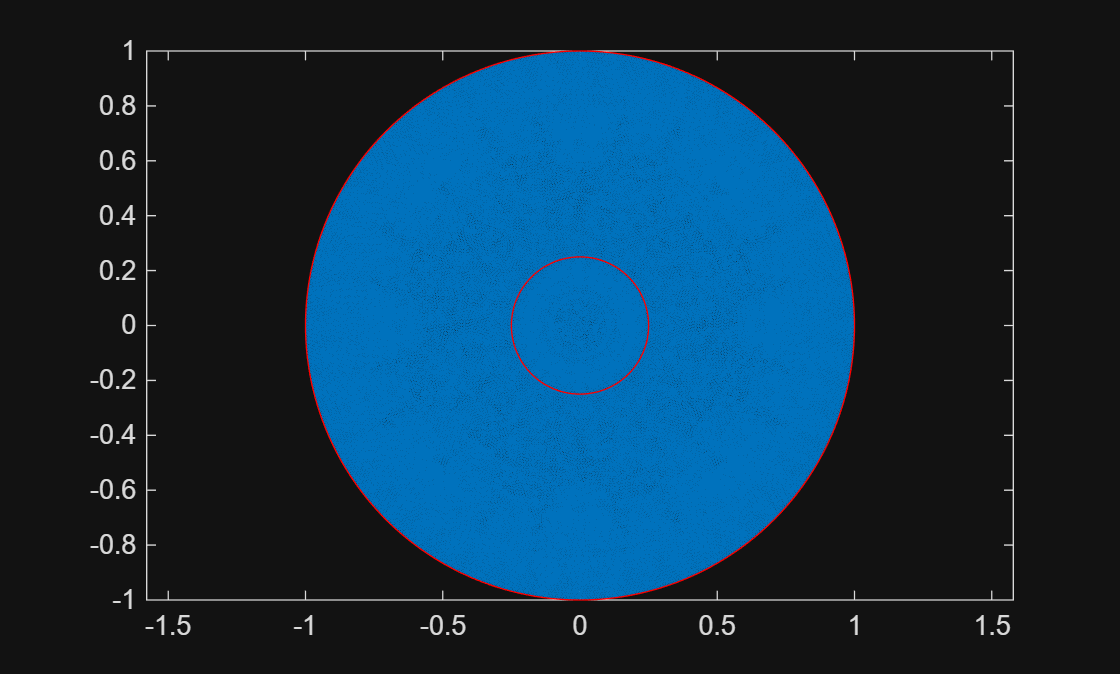

pdemesh(M);

TR = triangulation(M.Elements',M.Nodes');